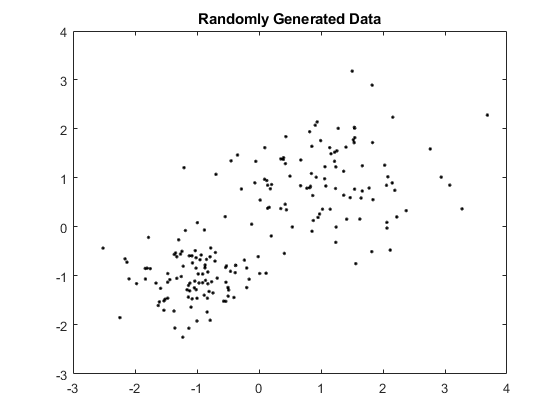

rng default; % For reproducibility
X = [randn(100,2)*0.75+ones(100,2);
    randn(100,2)*0.5-ones(100,2)];

figure;
plot(X(:,1),X(:,2),'.k');
title 'Randomly Generated Data';

rng(1); %
[idx,C] = kmeans(X,3);

x1 = -3:0.01:4;
x2 = -3:0.01:4;
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot

idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start',C);

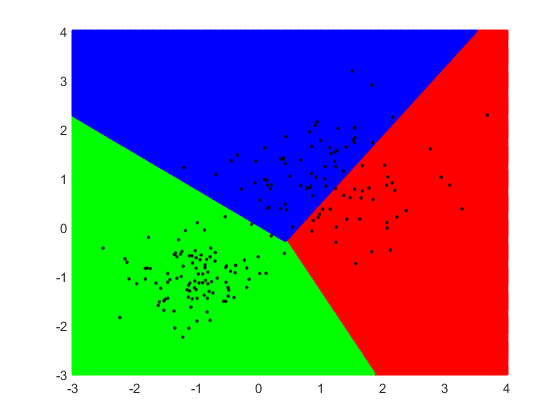

figure;
gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
    'rgb', '..');
hold on;
xlim([-3 4])
plot(X(:,1),X(:,2),'.k','MarkerSize', 6);
h = legend('example');
set(h, 'visible', 'off')
hold off;

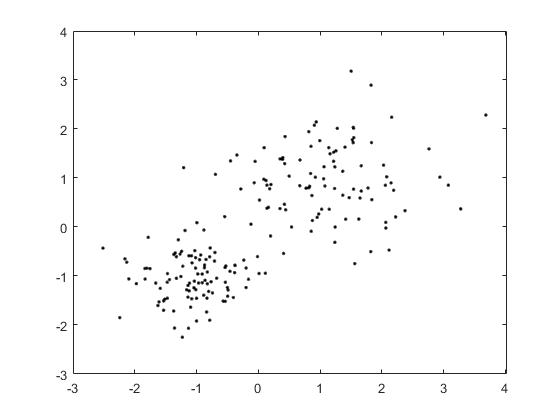

figure;
gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
    'www', '..');
hold on;
plot(X(:,1),X(:,2),'.k','MarkerSize', 6);
h = legend('example');
set(h, 'visible', 'off')
hold off;

% legend('Region 1','Region 2', 'Region 3','Data','Location','SouthEast');
